## Exercise 4.4

there are 7 points given, denoted as `x(i), `$0\leq i\leq 6$, hence we can use 4-order centered difference approximations to compute `x(2), x(3), x(4)`. use  and use 2-order forward/center/backword difference approximations to compute x(0), x(1), x(5), x(6)

xs = [0, 0.5, 1, 1.5, 2, 2.5, 3];
ys = [100, 147, 178, 192, 197, 199, 200];
h = 0.5;

ord4 = @(y, i, h) (-y(i+2)+8*y(i+1)-8*y(i-1)+y(i-2))/(12*h)

ord4 = function_handle with value:
    @(y,i,h)(-y(i+2)+8*y(i+1)-8*y(i-1)+y(i-2))/(12*h)


ord2_s = @(y, i, h) (-3*y(i)+4*y(i+1)-y(i+2))/(2*h)

ord2_s = function_handle with value:
    @(y,i,h)(-3*y(i)+4*y(i+1)-y(i+2))/(2*h)


ord2_e = @(y, i, h) (3*y(i)-4*y(i-1)+y(i-2))/(2*h)

ord2_e = function_handle with value:
    @(y,i,h)(3*y(i)-4*y(i-1)+y(i-2))/(2*h)


ord2 = @(y, i, h) (y(i+1)-y(i-1))/(2*h)

ord2 = function_handle with value:
    @(y,i,h)(y(i+1)-y(i-1))/(2*h)



ds = zeros(1, length(xs));
ds(1) = ord2_s(ys, 1, h)

ds =    110     0     0     0     0     0     0


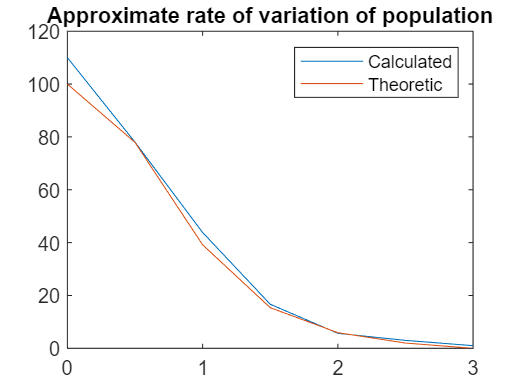

ds(2) = ord2(ys, 2, h);
ds(3) = ord4(ys, 3, h);
ds(4) = ord4(ys, 4, h);
ds(5) = ord4(ys, 5, h);
ds(6) = ord2(ys, 6, h);
ds(7) = ord2_e(ys, 7, h);

np = @(ys) 2 * ys - 0.01 * ys .^ 2;
dsp = np(ys);
errs = abs(dsp - ds) ./ dsp;

figure
plot(xs, ds, xs, dsp)
legend("Calculated", "Theoretic")
title("Approximate rate of variation of population")

## Exercise 4.5

Firstly, we'd computer the upper bound of errors of composite midpoint numerical integration. For every uniform interval, we have


$$\int_{x_i}^{x_{i+1}}f(x)dx-hf(c_i)\\=\int_{x_i}^{x_{i+1}}f(x)dx-hf(c_i)
\\=\int_{x_i}^{x_{i+1}}\left[f(c_i)+f'(c_i)(x-c_i)+\frac{f''(\zeta_i(x))}{2}(x-c_i)^2-f(c_i)\right]dx
\\=\frac{f''(\zeta_i(x))}{24}h^3$$


Take the sum over the $n$ intervals, we have


$$E_n=\sum_{i=1}^{n}\frac{f''(\zeta_i)h^3}{24}=\frac{h^2(b-a)}{24}\left[\frac{1}{n}\sum_{i=1}^nf''(\zeta_i)\right]=\frac{1}{24}f''(\zeta)(b-a)h^2,\quad\zeta\in[a,b]$$


In order that $|E_n|\leq E$, there must be $h\leq \sqrt{\frac{24E}{|f''(\zeta)|(b-a)}}$, or count of intervals $n\geq \left\lceil\sqrt{\frac{(b-a)^3 |f''(\zeta)|}{24E}}\right\rceil$$(*)$

**a)** $f_1(x)=\frac{1}{1+(x-\pi)^2}$, $f''(x)=\frac{6x^2-12\pi x+6\pi^2-2}{1+\pi^2-2\pi x+x^2}$ in $[0,5]$

hence $|f''(\zeta)|\leq |f''(\pi)|=2$. $n\geq 323$ by $(*)$, we'll take $n=350$.

Reference result: $\displaystyle\int_{0}^5 f_1(x) dx = \arctan(5-\pi)+\arctan{\pi}$

format long

f1 = @(x) 1 ./ (1 + (x - pi) .^ 2);
m1 = midpointc(0, 5, 350, f1);
m1

m1 =    2.339768329271377



disp("Reference results: ")

Reference results: 


m1_ref = vpa(atan(sym(5) - sym(pi)) + atan(sym(pi)), 20)

 
m1_ref =
 
                             2.3397662836684698665


disp("Absolute error: ")

Absolute error: 


e1 = abs(m1_ref - m1)

 
e1 =
 
                                           -5
                                  0.2045 10


**b) **$f_2(x)=e^x\cos(x)$, $f''_2(x)=-2e^x \sin x$ in $[0,\pi]$

hence $|f''(\zeta)|\leq |f''(1+\sqrt{2})|\\=2\exp(2\arctan (1+\sqrt{2}))\sin(2\arctan(1+\sqrt{2}))\in[14.9209770,14.9209771]$

$n\geq440$. we'll take $n=440$

Reference result: $\displaystyle\int_{0}^5 f_2(x) dx = \frac{-1-e^\pi}{2}$

format long

f2 = @(x) exp(x) .* cos(x);
m2 = midpointc(0, pi, 440, f2);
m2

m2 =  -12.070295038024705



disp("Reference results: ")

Reference results: 


m2_ref = vpa((sym(-1) - exp(sym(pi))) / 2, 20)

 
m2_ref =
 
                            -12.070346316389634504


disp("Absolute error: ")

Absolute error: 


e2 = abs(m2_ref - m2)

 
e2 =
 
                                  0.00005128


**c) **$f_3(x) = \sqrt{x(1-x)}$, $f_3''(x)=-\frac{1}{4(-(x^2-x))^{3/2}} \rightarrow \infty $as $x\rightarrow 0$ or $1$

hence it's hard to know when the error will decrease to $10^{-4$, so we will double the intervals (to ensure the knots used in last turn are also contained in next turn) each turn produces less than $5\times 10^{-5}$ difference.

Reference result: $\displaystyle\int_{0}^5 f_3x) dx = \frac{\pi}{8}$

format long

f3 = @(x) sqrt(x .* (1 - x));
old_m3 = inf;
n = 2;
while true
    m3 = midpointc(0, 1, n, f3);
    if abs(old_m3 - m3) < 10^-4
        break;
    end
    old_m3 = m3;
    n = n * 2;
end
m3

m3 =    0.392728796689731



disp("Reference results: ")

Reference results: 


m3_ref = vpa(sym(pi) / 8, 20)

 
m3_ref =
 
                            0.39269908169872415481


disp("Absolute error: ")

Absolute error: 


e3 = abs(m3_ref - m3)

 
e3 =
 
                                 0.0000297150


disp("Intervals: ")

Intervals: 


n

n =    256


## Additional Functions

function Imp = midpointc(a, b, M, fun, varargin) 
    %MIDPOINTC Composite midpoint numerical integration . 
    % IMP = MIDPOINTC (A,B,M,FUN) computes an approximation 
    % of the integral of the function FUN via the midpoint 
    % method (with M equal subintervals ). FUN accepts a 
    % real vector input x and returns a real vector value. 
    % FUN can be either an inline function , an anonymous 
    % function , or it can be defined by an external m-file. 
    % IMP=MIDPOINTC (A,B,M,FUN ,P1 ,P2 ,...) calls the function 
    % FUN passing the optional parameters P1 ,P2 ,... as 
    % FUN(X,P1 ,P2 ,...). 
    H = (b - a) / M; 
    x = linspace(a + H / 2, b - H / 2, M); 
    fmp = fun(x, varargin {:}) .* ones(1, M);
    Imp = H * sum(fmp);
end